%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Authors      :-  Manas Kumar Mishra, Niranjana Vannadil 
% Project name :-  SEA (Statistical Enhancement of Audio)
% Organization :-  IIITDM Kancheepuram
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Noisy clips
% 1. TempleNoisyclip1_Agra.mp3
% 2. TempleNoisyclip2_Agra.mp3
% 3. TempleNoisyclip1_Agra.wav
% 4. TempleNoisyclip2_Agra.wav
% 5. TestAudio4.wav

[samples, fsample] = audioread('TestSongs/TestAudio4.wav');

% player = audioplayer(samples, fsample);
% play(player);

fsample %sampling frequency of audio 

fsample = 44100

samples %Samples, right and left channel

samples =    -0.0131   -0.0108
   -0.0084   -0.0041
   -0.0028    0.0061
    0.0026    0.0156
    0.0060    0.0209
    0.0064    0.0199
    0.0049    0.0141
    0.0027    0.0070
    0.0017    0.0020
    0.0025    0.0014


% PSD Show

ShowPSD(samples, fsample);



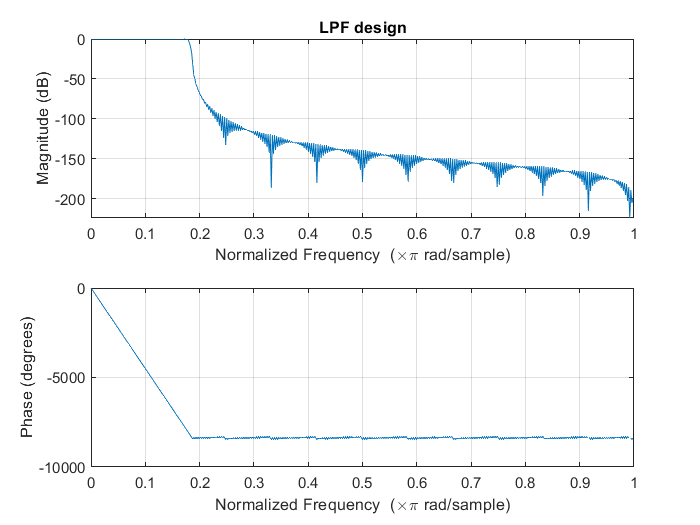

% Preprocessing step
Cutoff = 0.182;

filterLength =500;

filterCoff = impulseResponseOfFilterLPF(Cutoff, filterLength, 3);

NewSamples1 = myFIRFilter(samples(:, 1)', filterCoff);
NewSamples2 = myFIRFilter(samples(:, 2)', filterCoff);
NewSample = [NewSamples1', NewSamples2'];




% player = audioplayer(NewSample, fsample);
% play(player);


% PSD view
ShowPSD(NewSample, fsample);


% Output = MMSESTSA84(NewSample, fsample);

% player = audioplayer(Output, fsample);
% play(player);


a= rand(1, 44100)

W= ceil(0.032*44100)

W = 1412

Window = hamming(W);
overlappPerc=0.75;
sp = 1-overlappPerc

sp = 0.2500


Window=Window(:);
% a1= NewSample(:, 1)';
L=length(a);

SP=fix(W.*sp);

N=fix((L-W)/SP +1); %number of segments

repmat(1:W, N, 1);
repmat((0:(N-1))'*SP,1,W);
Index=(repmat(1:W,N,1)+repmat((0:(N-1))'*SP,1,W))'
hw=repmat(Window,1,N);
Seg=a(Index);
Seg=a(Index).*hw;

Seg

% Framing of the sample values
conSampleLength = 0.032

conSampleLength = 0.0320

WinLen = ceil(conSampleLength*fsample);
overlappPerc = 0.75;

[frame1, frame2]= Framing(samples,WinLen, overlappPerc, 1);
[FrameSize, NumOfFrame]=size(frame1)

FrameSize = 1412

NumOfFrame = 5980


% Fourier transform of the framed part
FSAMPLE1 = fft(frame1);
FSAMPLE2 = fft(frame2);



% F = FSAMPLE1(1:fix(end), :);

% Experiment 
A = [1, 2, 3, 4;
    2, 4, 5, 6;
    7, 8, 9, 10;
    11, 12, 13, 14];

F = A(1:fix(end))


% Convert Matrix into row vector 
F1 = FSAMPLE1(1:fix(end));
F2 = FSAMPLE2(1:fix(end));


% Magnitude term of fft term
F1_mag = abs(F1);
F2_mag = abs(F2);

% Phase term of the signal
F1_phase = angle(F1);
F2_phase = angle(F2);


% Asumming lambda_d (noise  variance) as constant value

InitSeg = 0.007;

%Noise Estimation
Perio1 = periodogram(abs(FSAMPLE1));
[N_PSD1,P1,alpha1,lambda_d1] = Noise_Estimation_Minimum_Statistics(Perio1);

lambd_d = 0.1588


Perio2 = periodogram(abs(FSAMPLE2));
[N_PSD2,P2,alpha2,lambda_d2] = Noise_Estimation_Minimum_Statistics(Perio2);

lambd_d = 0.3242



Alpha = 0.99;
% AlphaVec = Alpha*ones(1, FrameSize)
start = 1;
stop = FrameSize;

GammaFunction = gamma(1.5);

Gain1 = ones(1, FrameSize);
Gain2 = ones(1, FrameSize);
Gamma1 = Gain1;
Gamma2 = Gain2;

CleanedAudio1 = zeros(size(F1_mag));
CleanedAudio2 = zeros(size(F2_mag));
h=waitbar(0,'Wait...');

for i = 1:NumOfFrame
    % Something
    
    gammaNew1 = (F1_mag(start:stop).^2)./lambda_d1(i);
    gammaNew2 = (F2_mag(start:stop).^2)./lambda_d2(i);
    
    kssai1 =Alpha*(Gain1.^2).*Gamma1+(1-Alpha).*max(gammaNew1, 0) ;
    kssai2 =Alpha*(Gain2.^2).*Gamma1+(1-Alpha).*max(gammaNew1, 0) ;
    Gamma1 = gammaNew1;
    Gamma2 = gammaNew2;
    
    nu1 = Gamma1.*kssai1/(1+kssai1);
    nu2 = Gamma2.*kssai2/(1+kssai2);
    
    Gain1 = ((GammaFunction*sqrt(nu1))./Gamma1).*exp(-nu1/2).*[(1+nu1).*besseli(0, nu1/2)+nu1.*besseli(1, nu1/2)];
    Gain2 = ((GammaFunction*sqrt(nu2))./Gamma2).*exp(-nu2/2).*[(1+nu2).*besseli(0, nu2/2)+nu2.*besseli(1, nu2/2)];
    
    Indx1=find(isnan(Gain1) | isinf(Gain1));
    Gain1(Indx1)=kssai1(Indx1)./(1+kssai1(Indx1));
    
    Indx2=find(isnan(Gain2) | isinf(Gain2));
    Gain2(Indx2)=kssai1(Indx2)./(1+kssai2(Indx2));
    
    
    CleanedAudio1(start:stop)=Gain1.*F1_mag(start:stop);
    CleanedAudio2(start:stop)=Gain2.*F2_mag(start:stop);
    
    start = start+FrameSize;
    stop  = stop+FrameSize;
    
    waitbar(i/NumOfFrame,h,num2str(fix(100*i/NumOfFrame)));
end
close(h);


% Test1 = rand(1,100)
% test2 = zeros(1, 100)
% 
% Test1 = reshape(Test1, 10,10)
% test2 = reshape(test2, 10, 10)
% 
% Recon = OverlapAdd2(Test1, test2, FrameSize, ceil(0.25*FrameSize));

CleanedAudioMat1 = reshape(CleanedAudio1,FrameSize, NumOfFrame);
CleanedAudioMat2 = reshape(CleanedAudio2, FrameSize, NumOfFrame);

F1_phaseMat = reshape(F1_phase, FrameSize, NumOfFrame);
F2_phaseMat = reshape(F2_phase, FrameSize, NumOfFrame);

% testing with foreigner function
Clean1 = OverlapAdd2(CleanedAudioMat1, F1_phaseMat, FrameSize, ceil((1-overlappPerc)*FrameSize))

Clean1 = 	1.0e+06 *

   -0.0002
   -0.0000
    0.0002
   -0.0000
   -0.0001
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000


Clean2 = OverlapAdd2(CleanedAudioMat2, F2_phaseMat, FrameSize, ceil((1-overlappPerc)*FrameSize))

Clean2 = 	1.0e+05 *

   -0.0014
   -0.0004
    0.0008
    0.0001
   -0.0003
   -0.0001
    0.0002
   -0.0001
    0.0001
    0.0002



FinalAudio = [Clean1, Clean2];
player = audioplayer(FinalAudio, fsample);
play(player);

% NewSamples1 = myFIRFilter(FinalAudio(:, 1)', filterCoff);
% NewSamples2 = myFIRFilter(FinalAudio(:, 2)', filterCoff);
% NewSample = [NewSamples1', NewSamples2'];


% player = audioplayer(NewSample, fsample);
% play(player);


%Noise Estimation
% Perio1 = periodogram(abs(FSAMPLE1));
% [N_PSD1,P1,alpha1,lambda_d1] = Noise_Estimation_Minimum_Statistics(Perio1);

lambd_d = 0.1019

% 
% Perio2 = periodogram(abs(FSAMPLE2));
% [N_PSD2,P2,alpha2,lambda_d2] = Noise_Estimation_Minimum_Statistics(Perio2);

lambd_d = 0.2221